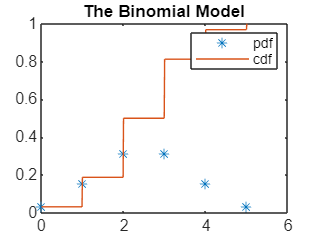

ans =   Legend (pdf, cdf) with properties:

         String: {'pdf'  'cdf'}
       Location: 'northeast'
    Orientation: 'vertical'
       FontSize: 9
       Position: [0.7654 0.8247 0.1212 0.0744]
          Units: 'normalized'

  Show all properties


clear all
clc

n=input("number of trials= ");
p=input("prob of success=");

k=0:n;

px=binopdf(k, n, p);

kreal = 0:0.01:n;
fx=binocdf(kreal, n, p);

plot(k, px, '*');
hold on;
plot(kreal, fx);
hold off;
title("The Binomial Model");
legend("pdf", "cdf")'